# Determine good solves

max = 32;

empty_allCosts.cost = [];
empty_allCosts.tst = [];
empty_allCosts.tsw = [];
empty_allCosts.kx = [];

all_costs = repmat(empty_allCosts,max,1);

for i = 1:max
    filename = "PSO_runs/run" + i + ".mat";

    out = load(filename);
    BestSol = out.out.BestSol; simParams = out.simParams;

    [cost,sols] = objective(BestSol.Position,simParams);
    figure
    plot(sols.t,sols.x);
    hold on
    plot(sols.t,sols.y);
    plot(sols.t,sols.th);
    plot(sols.t,sols.l);
    legend('x','y','th','l');
    titleName = i +" "+ cost;
    title(titleName);
    xlabel('time (s)');
    hold off

    all_costs(i).cost = cost;
    all_costs(i).tst = simParams.tst;
    all_costs(i).tsw = BestSol.Position(4);
    all_costs(i).kx = simParams.kx;
end

cost = zeros(1,max);

fileID = fopen("working_tst_tsw_kx.txt",'a');

for i = 1:max
    cost(i) = all_costs(i).cost;
    if (cost(i)<6e5)
        data = all_costs(i).tst + " " + all_costs(i).tsw + " " + all_costs(i).kx + " run" + i + "\n";
        fprintf(fileID,data);
    end
end

fclose(fileID);

plot(cost);

## Get region of operation

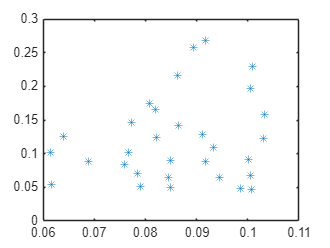

runs_working = readmatrix("working_tst_tsw_kx.txt");
tst = runs_working(:,1);
tsw = runs_working(:,2);
kx = runs_working(:,3);

plot(tst,kx,'*');


% run these 3 values with tst, kx, tsw as x, y, z through matlabs curve
% fitter to get the polynomial of best fit

## Save fit to file

save("PSO_runs/fits/fit_back.mat","fit_back");